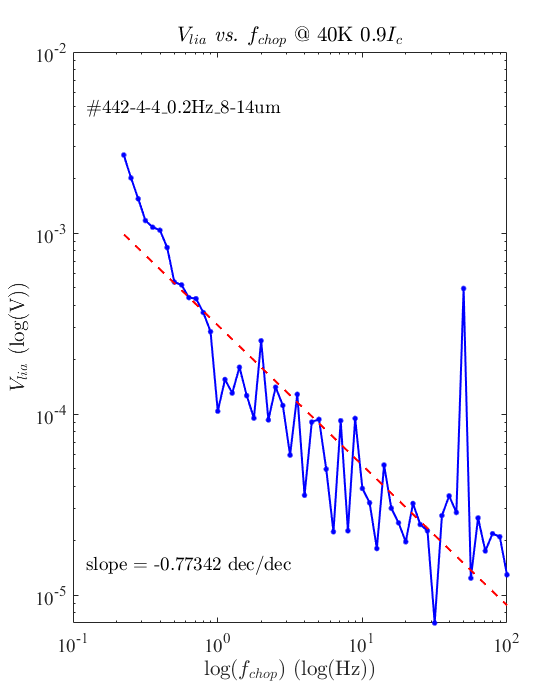

clear;clf("reset"); clc;
defaultPath = 'I:\WorkSpace\ResearchGroup\RecentWork\YBCO\Bolometer\Data\309test\20230916\';
Path = uigetdir(defaultPath); % Folder path of series test data
DevName = extract(Path,regexpPattern('\d+-\d+-\d+[\s\S]*'));
DevName = strrep(DevName{1},'_','\_');
File = dir(fullfile(Path,'*.mat')); % Extract all .mat files in the folder
FileNames = {File.name}';
load([Path, '\', FileNames{1}])
len = length(FileNames);
pat = regexpPattern('\d+.\d+K');
TempList =[];
RList = [];
CurrList = [];
VoltList = [];
for i = 1:len
    Reresult = extract(FileNames{i},pat);
    Temp = str2double(Reresult{1}(1:end-1));
    if ~ismember(Temp,TempList)
        TempList = [TempList, Temp];
    end
end
TempList = sort(TempList);
for temp = TempList
    matchCell = strfind(FileNames,num2str(temp,'%.1f'));
    matchIndex = ~cellfun('isempty', matchCell);
    matchIndex = find(matchIndex==1);
    for i = 1:length(matchIndex)
        load([Path, '\', FileNames{matchIndex(i)}])
    end
    R = 2*sqrt(2)*alignmentR(R,curr,volt);
    RList = [RList; R];
    CurrList = [CurrList; curr];
    VoltList = [VoltList; volt];
end

if exist('freq','var')
    f0 = figure(1);f0.Position(3:4) = [560 300]; 
    loglog(freq(2:end)/5, Vpp(2:end),'b.-',"LineWidth",1.5,"MarkerSize",12);hold on
    title(['$V_{lia}$ \emph{vs.} $f_{chop}$ @ ',num2str(TempList(1)),'K 0.9$I_{c}$'],"Interpreter","latex");
    xlabel('log($f_{chop}$) (log(Hz))',"Interpreter","latex");
    ylabel('$V_{lia}$ (log(V))',"Interpreter","latex");
    set(gca,'FontSize',14,'FontName','Times New Roman');
    %rmoutliers(log10(Vpp))
    logVpp = filloutliers(log10(Vpp),'makima','movmedian',20);
    pn = polyfit(log10(freq),logVpp,1);
    Vppfit = polyval(pn,log10(freq));
    plot(freq(2:end)/5, 10.^Vppfit(2:end),'r--',"LineWidth",1.5);hold off
    text(0.03,0.9,['\#',DevName],"FontSize",14,"Units","normalized","Interpreter","latex")
    text(0.03,0.1,['slope = ',num2str(pn(1)),' dec/dec'],"FontSize",14,"Units","normalized","Interpreter","latex")
end

f1 = figure(2);f1.Position(3:4) = [560 700]; 
colororder(cool(length(TempList)));

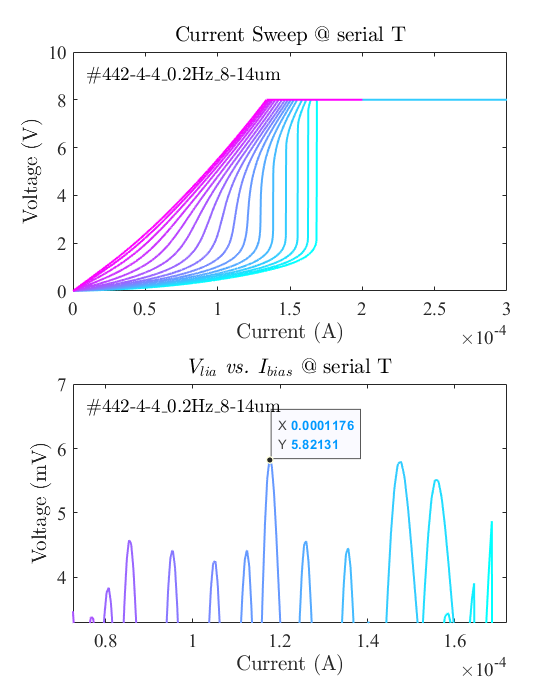

subplot(2,1,1)
plot(CurrList', VoltList',"LineWidth",1.5);
title('Current Sweep @ serial T',"Interpreter","latex");
text(0.03,0.9,['\#',DevName],"FontSize",14,"Units","normalized","Interpreter","latex")
xlabel('Current (A)',"Interpreter","latex");
ylabel('Voltage (V)',"Interpreter","latex");
set(gca,'FontSize',14,'FontName','Times New Roman');
subplot(2,1,2)
plot(CurrList',1e3*RList',"LineWidth",1.5);
title('$V_{lia}$ \emph{vs.} $I_{bias}$ @ serial T',"Interpreter","latex");
text(0.03,0.9,['\#',DevName],"FontSize",14,"Units","normalized","Interpreter","latex")
xlabel('Current (A)',"Interpreter","latex");
ylabel('Voltage (mV)',"Interpreter","latex");ylim([0 25])
set(gca,'FontSize',14,'FontName','Times New Roman');

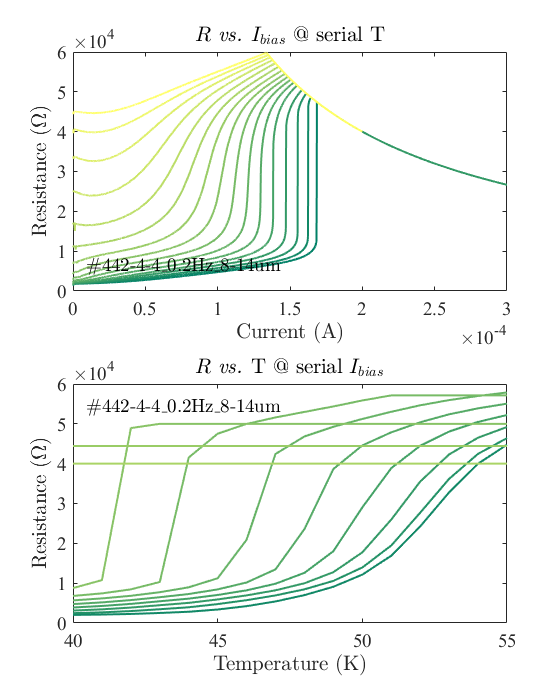

f2 = figure(3);f2.Position(3:4) = [560 700]; 
subplot(2,1,1)
colororder(cool(floor(1.4*length(TempList))));
plot(CurrList',VoltList'./CurrList',"LineWidth",1.5);
title('$R$ \emph{vs.} $I_{bias}$ @ serial T',"Interpreter","latex");
text(0.03,0.1,['\#',DevName],"FontSize",14,"Units","normalized","Interpreter","latex")
xlabel('Current (A)',"Interpreter","latex");
ylabel('Resistance ($\Omega$)',"Interpreter","latex");
set(gca,'FontSize',14,'FontName','Times New Roman');
subplot(2,1,2)
colororder(summer(length(TempList)));
currSection = 0:20e-6:200e-6;
ResisList = [];
for i=1:length(TempList)
    Resis = interp1(CurrList(i,:),VoltList(i,:)'./CurrList(i,:)',currSection);
    ResisList = [ResisList; Resis];
end
plot(TempList,ResisList,"LineWidth",1.5)
title('$R$ \emph{vs.} T @ serial $I_{bias}$',"Interpreter","latex");
text(0.03,0.9,['\#',DevName],"FontSize",14,"Units","normalized","Interpreter","latex")
xlabel('Temperature (K)',"Interpreter","latex");
ylabel('Resistance ($\Omega$)',"Interpreter","latex");
set(gca,'FontSize',14,'FontName','Times New Roman');

function R_extend = alignmentR(R,curr,volt)
    R = R(40:end);
    R_extend = interp1(linspace(min(curr),max(curr),length(R)),R,curr);
    R_extend(volt>7.999) = 0;
    % plotyy(curr,R_extend,curr,volt);
end